% Draft: Analysis 

## Bayesian Methods

## The State-Space System

A variant of the Nelson-Siegel model, the Dynamic Nelson Siegel (DNS) or the Diebold-Li model is a reparameterization of the original equation. Given the time to maturity $\tau$, and date $t$ when the yield is observed, the yield $y_t(\tau)$from the Diebold-Li model is a function of four parameters: 


$$y_t(\tau_m) = L_t + S_t \left(\frac{1 - e^{-\lambda \tau_m}}{\lambda \tau_m} \right)
+ C_t \left(\frac{1 - e^{-\lambda \tau_m}}{\lambda \tau_m} - e^{-\lambda \tau_m} \right)$$
                          
$$\left(1\right)$$


Here, $L_t$ is the level or the the long-term factor as it influences long-term bonds, $S_t$ is the slope or short-term factor, and $C_t$ is the curvature or the medium-term factor.  $\lambda$ determines the maturity at which the loading on the curvature is maximized, and governs the exponential decay rate of the model. 

The level, slope and curvature in the Diebold-Li model follow a first order vector autoregressive process or VAR(1), which has a state-space representation as follows: 


$$ \pmatrix {L_t - \mu_L \cr S_t - \mu_S \cr C_t - \mu_C}
= \pmatrix {a_{11} \ a_{12} \ a_{13} \cr a_{21} \ a_{22} \ a_{23}
\cr a_{31} \ a_{32} \ a_{33}}
\pmatrix{L_{t-1} - \mu_L \cr S_{t-1} - \mu_S \cr C_{t-1} - \mu_C}  + 
\pmatrix {\eta_t(L) \cr \eta_t(S) \cr \eta_t(C)}  $$
                             
$$\left(2\right)$$


The corresponding measurement equation is: 


$$ \pmatrix{y_t(\tau_1) \cr y_t(\tau_2) \cr \vdots \cr
y_t(\tau_M)} =
\pmatrix{1 \ \frac{1 - e^{-\lambda \tau_1}}{\lambda \tau_1} \ 
\frac{1 - e^{-\lambda \tau_1}}{\lambda \tau_1} - e^{-\lambda \tau_1} \cr
1 \ \frac{1 - e^{-\lambda \tau_2}}{\lambda \tau_2} \ 
\frac{1 - e^{-\lambda \tau_2}}{\lambda \tau_2} - e^{-\lambda \tau_2} \cr
\vdots \cr
1 \ \frac{1 - e^{-\lambda \tau_M}}{\lambda \tau_M} \ 
\frac{1 - e^{-\lambda \tau_M}}{\lambda \tau_M} - e^{-\lambda \tau_M}}
\pmatrix {L_t \cr S_t \cr C_t} 
+ \pmatrix {\epsilon_t(\tau_1) \cr \epsilon_t(\tau_2) \cr \vdots \cr
\epsilon_t(\tau_M)} $$
              
$$\left(3\right)$$


In matrix notation, we can write the state-space system for the three-dimensional vector of the mean adjusted factors  $f_t$ and observed yields $y_t$: 


$$(f_t - \mu) = A(f_{t-1} - \mu) + \eta_t$$
                                                                                   
$$\left(4\right)$$



$$y_t = \Lambda f_t + \epsilon_t $$
                                                                                                        
$$\;\left(5\right)$$


where, $\eta_t$ and $\epsilon_t$ are orthogonal to each other and follow white noise processes with the following  distribution:   

                          
$$\left\lbrack \begin{array}{c}
\eta_t \\
\epsilon_t 
\end{array}\right\rbrack \sim \textrm{WN}\left(\;\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\Sigma_{\eta }  & 0\\
0 & \Sigma_{\epsilon } 
\end{array}\right\rbrack \right)\;$$


The mean-adjusted factors describe the latent states:


$$x_t = f_t - \mu$$
                                                                                                           
$$\left(6\right)$$


Susbtituting equation (6) in (4), the state-space system of the Diebold-Li model is characterized as: 


$$x_t = Ax_{t-1} + \eta_t$$
                                                                                                    
$$\left(7\right)$$


Diebold and Li (2006) converted the prices of the government bonds to unsmoothed Fama-Bliss US treasury zero-coupon yields to develop the Dynamic Nelson Siegel model to approximate the dynamic nature of the structure of factors. However, I have constructed the DNS by directly using the treasury yields from [FRED](https://fred.stlouisfed.org/). I have aggregated the monthly data on the treasury yields of various maturities, ranging from 3 month to 30 years. Depicting a snapshot of the current yield levels in the market, each of the ten series has both a cross-sectional and a temporal dimension. 

% has data from October 31, 1993 to August 30, 2020 collected from FRED
% no missing values
tres = readtable("data_df.csv");
tres_big = readtable("big_data.csv");



% extract the "Dates" column and store it as "dates" table
dates = table2array(tres(:, 'Date')); 
exog = table2array(tres_big(:, {'tcu_ch', 'pce_ch', 'unrate', 'effr'}));

% extract column names of table "tres"
tres.Properties.VariableNames;
tres_big.Properties.VariableNames;

% removes the "Date" column from "tres"
tresc= removevars(tres,{'Date'});
data = table2array(tresc);


% removes the "Date" and other columns from "tres_big"
tresc_big= removevars(tres_big,{'Date', 'tcu_ch', 'unrate'});
%format shortG
data_big = table2array(tresc_big);


% DataTable: has columns' names of yields of varying ttm
% and row names for each date

% yields of 10 term to maturity (TTM) in months
ttm =[3; 6; 12; 24; 36; 60; 84; 120; 240; 360];

% yields = dataset on 10 different maturities for in-sample modeling
yields = data(1:end,:);      % in-sample yields for estimation

% yields_big = dataset on 10 different maturities + other 55 vars for in-sample modeling
yields_big = data_big(1:end,:);      % in-sample yields for estimation

## Two-Step Diebold-Li Model with Fixed $\lambda$

Finding the ex-ante value of the latent factors is tantamount to finding the ex-ante values of the yield curve as it is a function of the factors. Then, I have constructed the Diebold-Li model with the explanatory variables as factor forecasts. The two-step approach of fitting the Diebold and Li model and estimating the parameters of their yield curve is:

- Firstly, I have kept $\lambda$ fixed and estimated the level, slope, and curvature parameters for each of the daily values of the yield curve. We can  consider the regression coefficients from OLS as the three factors. Repeating this process for all observed yield curves yields a three-dimensional matrix of estimates of the three latent factors. Keeping $\lambda$ fixed simplifies the estimation method from non-linear least squares to OLS, which creates a static Nelson Siegel model at each month.

- Secondly, I have fitted $\textrm{VAR}\left(1\right)$ to the time series of factors derived in the first step.

In the Nelson-Siegel model, $\lambda_t$ determines the time to maturity at which the loadings on the curvature, or the medium-term factor are maximized. These are usually yields that mature in 24 to 36 months.  Dielbold and Li (2005) set $\lambda_t =0\ldotp 0609\;$ for all $t\ldotp$ This is the value at which the loading on the curvature (medium-term factor) is maximized occurs at 30 months. Below, I have shown the first-step in the Diebold-Li model, and accumulated the coefficients (factor loadings) and the residuals from the OLS model. The factor loadings on $\beta_1 ,\beta_2$ and $\beta_3$ govern the level, slope and curvature, respectively, of the yield curve. Then, I plotted the factor loadings in one graphs. 

lambda0 = 0.0598;
% X is a 10 by 3 matrix: as there is data on 10 different yields and 3 betas
% factors
X = [ones(size(ttm)) (1-exp(-lambda0*ttm))./(lambda0*ttm) ...
    ((1-exp(-lambda0*ttm))./(lambda0*ttm)-exp(-lambda0*ttm))];


% size(yields,1): queries the length of the 1st dim of 'yields" : 324
% betas = zeros(324, 3)
% stores the betas
betas = zeros(size(yields,1),3);

% numel : returns the number of elements in array "ttm" : 10
% resid = zeros(324, 10)
% stores the resid from the OLS model
resid = zeros(size(yields,1),numel(ttm));

% fix lambda and compute the 3 betas params for each monthly observation of the
% yield curve by OLS
% the betas coefficients from the OLS regression are equivalent to the 3
% factors: level, slope, and curvature
% collect the 3D time-series of the betass (estimated factors) by fitting
% the OLS model on each yield curve observed
% store the betas (regression coefficients) and resid

for i = 1:size(yields,1) 
    OLSmod = fitlm(X, yields(i,:)', 'Intercept', false);
    betas(i,:) = OLSmod.Coefficients.Estimate';
    
    % raw residuals (observed - fitted values) from the OLS model 
    resid(i,:) = OLSmod.Residuals.Raw'; 
end

The descriptive statistics indicates that the curvature factor is most volatile, followed by the level and slope factors, respectively. 

After fitting the three-dimensional data of factors, I have fit a first$-$order VAR model  on this estimated time series of factors. Using the multivariate least squares (MLS) method, which is a multivariate analog to the OLS done equation-by-equation, I estimated the coefficeint matrix A. The state transition matrix in equation (7) is $X_t = AX_{t-1} + \eta_t$  

Assuming that $E\left\lbrack \eta_t \;X_{t-1}^T \right\rbrack =0,$ and the error from equation (7) is $\eta_t =X_t -{\textrm{AX}}_{t-1}$                             $\left(8\right)$

Substituting equation (8) in endogeneity assumption equation, $E\left\lbrack \left.{\left(X_t -{\textrm{AX}}_{t-1} \right)X}_{t-1}^T \right)\right\rbrack =0$


$$\Rightarrow E\left\lbrack X_t \;X_{t-1}^T \right\rbrack =A\;E\left\lbrack X_{t-1} \;X_{t-1}^T \right\rbrack \Rightarrow A=E\left\lbrack X_t X_{t-1}^T \right\rbrack \;E{\left\lbrack X_{t-1} \;X_{t-1}^T \right\rbrack }^{-1}$$


As the data has $T$ time periods of observations, let $X_0$ and $X_1$ be matrices of length $\left(T-1\right)\times n$, then the estimator of A is given by: $\hat{A} =X_0 {\;X}_1^T {\left(X_1 \;X_1^T \right)}^{-1}$

 % current betas values with one less observation
betas0 = betas(1:end-1,:);

% (t-1) lagged betas values 
betas1 = betas(2:end,:); 

% coefficient matrix of the lagged betass
A = (betas1'*betas0)/(betas0'*betas0) 

A =     0.9995    0.0150   -0.0080
   -0.0166    0.9201    0.0501
   -0.0081    0.0228    0.9568


Now, I have calculated the variance covariance matrix of the residuals from the VAR(1) and OLS model from the 2-step Diebold-Li method. These matrices are $\Sigma_{\eta }$ and $\Sigma_{\epsilon }$, respectively from the distribution of the errors discussed earlier:


$$\left\lbrack \begin{array}{c}
\eta_t \\
\epsilon_t 
\end{array}\right\rbrack \sim \textrm{WN}\left(\;\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\Sigma_{\eta }  & 0\\
0 & \Sigma_{\epsilon } 
\end{array}\right\rbrack \right)\;$$


% % Innovations of VAR and its variance-cov matrix
% var_error = betas0' - A*betas1'; var_error = var_error';
% sigma_eta = cov(var_error);
% 
% disp_sigma_eta = {"variance Covariance Matrix of the VAR(1) Innovations:";...
%     "----------------------------------";...
%     sigma_eta};
% cellfun(@disp,disp_sigma_eta)
% 
% 
% % H0: 10-by-10 covariance matrix of the residuals from the OLS model
% sigma_epsilon = cov(resid);
% disp_sigma_epsilon = {"variance Covariance Matrix of the Residuals from OLS:";...
%     "----------------------------------";...
%     sigma_epsilon};
% cellfun(@disp,disp_sigma_epsilon)



VAR(p) is:

$f_{t+h} =a_0 +\sum_{i=1}^p A_j f_{t-j} +\epsilon_t$ , $\forall \;t=1,2,\ldotp \ldotp \ldotp ,T\;,$

where ${\;\epsilon }_t$ is a $\left(K\times 1\right)$ vector of errors, $A_j$ is a $\left(K\times K\right)$ matrix of coefficients with *p *lags of *y.* As there are 3 latent factors in this model, $K=3\ldotp$ In the multivariate normal representation, f is a $\left(\textrm{RT}\times 1\right)$ vector, wherein all the observations of the level variable (for all time periods), followed by those of the slope and curvature are stacked in one column vector. 

In matric-variate normal distribution terms, the VAR is $F=\textrm{XA}+E,\;$where *E *and $\epsilon$ are vectorization of errors similar to those of $y$ and F*. *  $A={\left\lbrack a_0 \;,\;A_1 ,\ldotp \ldotp \ldotp ,A_p \right\rbrack }^T \Rightarrow \alpha =\textrm{vec}\left(A\right)\ldotp$ Thus $\alpha$ is a $\left(\textrm{RK}\times 1\right)$ vector.

$y=\left(I_K \otimes X\right)\;\alpha +\epsilon$, where $\epsilon \sim N\left(0,\Sigma \otimes I_M \right)$

From among the four prior available, I will use Monte Carlo integration when analytical results are present in diffuse and Minnesota prior. Alternatively, I will use Gibbs Sampling when employing the Independent Normal-Wishart prior. Here, I will take "burn-in" draws and store only those draws that have converged.

% Originally written by Koop and Korobilis (2009),I have modified it. 


% Direct h-step ahead forecasts where there are p lags of F:
% f(t+h) = A0 + f(t) x A1 + ... + f(t-p+1) x Ap + e(t+h)



% VARcoef is the (R x K) matrix of VAR coefficients,
% alpha is the RM x 1 column vector of vectorized VAR coefficients, i.e.
% alpha = vec(VARcoef), and sigma_eps is a covariance matrix of dimension (K x K).


randn('seed',2); 
rand('seed',2); 


% ================== Introductory Specifications ===================

% Specify the VAR model

% 1: if there is an intercept; 0 otherwise
intercept = 1;  


% 1: forecast h-step ahead, 0: no forecasts
% where h = forecast horizon
forecast = 1;     

% number of times to draw from the predictive density
% for each generated draw of the parameters 
repeat = 50;         
 
% forecast horizon or periods
horizon = 1;  

% 1: Calculate impulse resp, 0: no impulse resp
impulses = 1;  

% Compute impulse resp for h_irf number of periods or horizons
h_irf = 24;           

% Set prior_dist for the BVAR model:

% prior_dist = 1 is Diffuse or'Jeffreys' prior
% prior_dist = 2 is Minnesota 
% prior_dist = 3 is Normal-Wishart          
% prior_dist = 4 is Independent Normal-Wishart
% prior_dist = 5 is SSVS in mean-Wishart            
% prior_dist = 6 is SSVS in mean-SSVS in covariance 

% use MC integration when prior_dist = 1,2,3, and
% use Gibbs sampler when prior_dist = 4,5,6


prior_dist = 6;  

% Number of lags on dependent variables
if prior_dist == 1
    p = 4;
    
else p = 13;
end
            

% Setting the Gibbs Sampler 


% Number of saved draws (500,000 draws)
%num_draw_save = 500000;  
num_draw_save = 10000; 

% Number of discarded or (burn-in) draws (400,000)
num_draw_discard = 9000;         


% Parameter values converge to the true values when we use analytical results 
if prior_dist ==1 || prior_dist == 2 || prior_dist == 3
    num_draw_discard = 0*num_draw_discard;
end

% Total number of draws is the sum of saved and discarded draws
num_total_draws = num_draw_save + num_draw_discard;  

% Prints every "iterations"-th iteration
iterations = 3000;       


%=========================== Organizing the Data ===========================

% the data is "betas" i.e the latent factors: level, slope and curvature
% betas is a (T by K) matrix 

betas_exog = [betas(3:end,:) exog];

% nobs = number of observations in the dataset
[nobs, K] = size(betas_exog);

% Model specification for direct forecasts
if forecast==1
    
    % Check if the input is incompatable
    if horizon <=0 
        error('The forecasting horizon number is incorrect')
    end
    
    % VAR specification based on the forecasting method
   
        F1 = betas_exog(horizon + 1:end,:);
        F2 = betas_exog(2:end-horizon,:);
        nobs = nobs - horizon - 1;
   
else
   F1 = betas_exog;
   F2 = betas_exog;
end
        
% Generate lagged values of F matrix, 
% which will constitute a variable of the X matrix
% F is [T x K]. ylag is [T x (Mp)]

Flag = lagf(F2,p); 

% Define X matrix that consists of the intercept, and 
% the lags of the latent variables


if intercept
    
    % ones(nobs-p,1): create a vector of 1s of dim(nobs-p)
    % X1 matrix consists  a vector of constant 1s and lagged betas
    
    X1 = [ones(nobs-p,1) Flag(p+1:nobs,:)];
else
    X1 = Flag(p+1:nobs,:);  
end

% size of final matrix X after taking the lags
% X1 is the name of the final matrix
% R is (4 by 3) as it includes a constant
% nobs3 and R: display the number of rows and columns in X1, respectively
[nobs3, R] = size(X1);


% Create the block diagonal matrix G such that y = beta * G + error
% eye(K) returns an K -by- K identity matrix with ones on the main diagonal 
% and zeros elsewhere
% returns the Kronecker tensor product of matrices eye(K) and X1

G1 = kron(eye(K),X1);


% F matrix: First row of Flag has 0s
% Delete the first row from Flag to match the dimensions of X matrix
% final F matrix inputted in the VAR

F1 = F1(p+1:nobs,:); 

% T is the number of actual time series observations of F and X
T = nobs - p;


%=========================== Set up of the Forecasting Model ===========================

% Keep the last "horizon" num of observations to evaluate (pseudo-)forecasts
if forecast==1
    
    % matrix F_pred stores 500,000 forecasted draws of each latent factor
    F_pred = zeros(num_draw_save*repeat,K); 
    
    % vector pred_likhood stores the predictive likelihood
    pred_likhood = zeros(num_draw_save,1);            
    
    % Direct forecasts: store the last observation to evaluate the model's
    % performance
        F = F1(1:end-56,:);          
        X = X1(1:end-56,:);
        G = kron(eye(K),X);
        T = T - 1;
        
% No forecasts: keep all observations   
else 
    F = F1;
    X = X1;
    G = G1;
end

%=========================== Set up of Impulse Response Function ==============================

% Create matrices to store forecasts
if impulses == 1;
%     
     % impulse resp to a shock in level
     imp_level = zeros(num_draw_save,K,h_irf); 
     
    % impulse resp to a shock in slope
     imp_slope = zeros(num_draw_save,K,h_irf); 
     
    % impulse resp to a shock in curvature
     imp_curv = zeros(num_draw_save,K,h_irf);  
     
    % impulse resp to a shock in level
     imp_tcu_ch = zeros(num_draw_save,K,h_irf); 
    
    % impulse resp to a shock in level
     imp_pce_ch = zeros(num_draw_save,K,h_irf); 
    
    % impulse resp to a shock in slope
     imp_unrate = zeros(num_draw_save,K,h_irf); 
    
    % impulse resp to a shock in curvature
     imp_effr = zeros(num_draw_save,K,h_irf);  
   
     bigj = zeros(K,K*p);
     bigj(1:K,1:K) = eye(K);
end


%=========================== Initialize the Parameters ====================================

% Obtain the Maximum Likelihood estimators

% estimate a matrix of regression coefficients  (A_ols is named as phi in my thesis)
% dim(A_ols) = 4 x 3 = (r x k)

A_ols = inv(X'*X)*(X'*F); 

% A_ols_vec = vec(A_ols): stack the matrix cols into a vector of params
% each column is stacked one below the other
% creates an (rk x 1) = (12 x 1) vector of coefficients from A_ols

A_ols_vec = A_ols(:);  
 
% Sum of squared errors of the VAR
% dim(sse) = 3 x 3
sse = (F - X*A_ols)'*(F - X*A_ols);   
sigma_ols = sse./(T-R+1);

% Initialize Bayesian posterior parameters using the OLS values

% single draw from alpha's posterior
% alpha is (12 x 1) vector of the 9 VAR coefficients and 3 constants
% (alpha is named as A in my thesis)

alpha = A_ols_vec;     

% single draw from the posterior of VARcoef of dim 4 x 3
VARcoef = A_ols;  

% SSE based on each draw of VARcoef
sse_gibbs = sse; 

%  single draw from the posterior of sigma_eps
sigma_eps = sigma_ols; 

% eye(K): identity matrix of dim 3
IXF =  kron(eye(K),(X'*F));


% Store the posterior draws


% initially, create a matrix of zeros of dim(12,000 x 12)
% then save posterior draws of alpha
alpha_draws = zeros(num_draw_save,R*K); 

% initially, create a matrix of zeros of dim(12,000 x 4 x 3)
% then save posterior draws of VARcoef
VARcoef_draws = zeros(num_draw_save,R,K);

% initially, create a matrix of zeros of dim(12,000 x 3 x 3)
% then save posterior draws of sigma_eps
sigma_draws = zeros(num_draw_save,K,K);   

Now, I have loaded the file that contains the hyperparameters inserted in the prior distributions. These hyperparameters are used in the BVAR model. The file comprises of a function that stores priors for each of the aforementioned four priors. 

In the Minnesota prior, I have estimated the VAR coefficient matrix A, where $A\sim N\left(A_{\textrm{mp}} \;,\Sigma_{\textrm{mp}} \;\right)$


$$A_{\textrm{mp}} =\left\lbrace \begin{array}{ll}
0\ldotp 95, & \textrm{for}\;a_{\textrm{ii}} \;i\ldotp e\ldotp \textrm{the}\;\textrm{coefficient}\;\textrm{associated}\;\textrm{with}\;\textrm{the}\;\textrm{first}\;\textrm{lag}\\
0, & \textrm{for}\;a_{\textrm{ij}} ,\;\textrm{where}\;i\not= j
\end{array}\right.$$


The Minensota prior presupposes the prior covariance matrix $\Sigma_{\textrm{mp}}$ to be diagonal, determined by the three hyperparameters$-{\;d}_1 ,d_2 ,d_3$ through the indicator funtion as follows:


$$\Sigma_{i,\textrm{jj}} =\left\lbrace \begin{array}{ll}
\frac{d_1 }{l^{\;2} }, & \textrm{when}\;\textrm{the}\;\textrm{coefficient}\;\textrm{is}\;\textrm{the}\;\textrm{own}\;\textrm{lag}\;\textrm{itself}\;\\
\frac{d_2 \;\sigma_{\textrm{ii}} }{l^{\;2} \sigma_{\textrm{jj}} }, & \textrm{when}\;\textrm{the}\;\textrm{coefficients}\;\textrm{are}\;\textrm{the}\;\textrm{lags}\;\textrm{of}\;\textrm{different}\;\textrm{variables}\;i\not= j
\end{array}\right.$$


Since, there is one lag for the variables, $l=1:$


$$\Sigma_{i,\textrm{jj}} =\left\lbrace \begin{array}{ll}
d_1 , & \textrm{when}\;\textrm{the}\;\textrm{coefficient}\;\textrm{is}\;\textrm{the}\;\textrm{own}\;\textrm{lag}\;\textrm{itself}\;\\
\frac{d_2 \;\sigma_{\textrm{ii}} }{\sigma_{\textrm{jj}} }, & \textrm{when}\;\textrm{the}\;\textrm{coefficients}\;\textrm{are}\;\textrm{the}\;\textrm{lags}\;\textrm{of}\;\textrm{different}\;\textrm{variables}\;i\not= j
\end{array}\right.$$


% Hyperparameters in the prior distribution used in the BVAR model

prior_dist_hyper_exog;

I have displayed the analytical posterior results for the first three priors - Diffuse, Minnesota, and Normal-Wishart. I implemented Markov Chain Monte Carlo simulations when using the Independent Normal-Wishart prior. In this case, the parameter values are contingent upon 15,000 Markov Chain Monte Carlo (MCMC) draws, out of which I have discarded the first 2000 draws. As impulse response functions are non-linear functions of the VAR coefficients, and $\Sigma ,$ I have simulated to get the posterior results from all four priors. 

 In implementing the Gibbs sampler, I simulated the samples by drawing each random variable from the conditional posterior distribution, one variable at a time. As I initialized the algorithm with random values, the simulated samples in the initial iterations may not always be representative of the target posterior distribution. As the target joint posterior distribution is the stationary distribution, I ran the algorithm for a large number of iterations to ensure that the values in the markov chain converge to the target posterior distribution. Burn-in samples allow the markov chain to reach its equilibrium or stationary distribution if the starting point is not suitable (as typically samples from the initial iterations are not from the target posterior distribution). Discarding the initial samples or draws (that are not stationary) precludes oversampling regions with low probabilities.

%========================== Sampling Begins Here ================================


% Begin the for loop for Gibbs Sampling

% repeat the iterations 15,000 times i.e. take 15,000 draws
for iter_rep = 1:num_total_draws  
    
    
    
    % ---------  From Diffuse prior_dist, draw VARcoef and sigma_eps ---------
    if prior_dist == 1
        
        % Posterior of (alpha|sigma_eps,Data) ~ Normal
        % kronecker product of sigma_eps and inverse of (X'X)
        V_posterior = kron(sigma_eps,inv(X'*X));
        
        % Draw alpha
        
        % chol(V_posterior)': factorizes symmetric positive definite matrix
        % V_posterior into a lower triangle 
        % randn(R*K, 1): creates a normally distributed vector of 
        % R*K = 4 x 3 = 12 rows
        
        alpha = A_ols_vec + chol(V_posterior)'*randn(R*K,1);
        
        % Draw VARcoef 
        
        % alpha is a (12 x 1) vector. reshape it into (R x K) vector
        VARcoef = reshape(alpha,R,K);     
        
        % Draw sigma_eps
        
        % Posterior dist.:(sigma_eps|data) ~ inverse Wishart(sse_gibbs,T-K) 
        % check 2.2.1 in pp 5 of the manual
        sigma_eps = inv(wishart(inv(sse_gibbs),T-R));
        
        
        
    % --------- From Minnesota prior_dist, draw VARcoef and sigma_eps ---------
    elseif prior_dist == 2
        
      % Here, we know the matrix sigma_eps
      % the prior_dist_hyper_exog function contains the form of sigma_eps    
        
        
        % Draw VARcoef
        
        % for all K = 3 number of factors
        for i = 1:K
            V_posterior = inv(inv(V_prior_dist((i-1)*R+1:i*R,(i-1)*R+1:i*R)) + ...
                inv(sigma_eps(i,i))*X'*X );
            
            a_posterior = V_posterior*(inv(V_prior_dist((i-1)*R+1:i*R, ...
                (i-1)*R+1:i*R))*a_prior_dist((i-1)*R+1:i*R,1) + ...
                inv(sigma_eps(i,i))*X'*F(:,i));
            
            % Draw alpha
            alpha((i-1)*R+1:i*R,1) = a_posterior + chol(V_posterior)'*randn(R,1); 
        end
        
        % In terms of VARcoef, create a draw
        VARcoef = reshape(alpha,R,K); 
        

        
        
        
    % --------- From the Normal-Wishart prior_dist, draw VARcoef and sigma_eps
    elseif prior_dist == 3
        
        
        % Relevent posterior params from pp 8 Koop and Korobilis (2009)
        
        
        V_posterior = inv( inv(V_prior_dist) + X'*X ); 
        A_posterior = V_posterior*(inv(V_prior_dist)*A_prior_dist + X'*X*A_ols);
        a_posterior = A_posterior(:);
    
        S_posterior = sse + S_prior_dist + A_ols'*X'*X*A_ols +... 
        A_prior_dist'*inv(V_prior_dist)*A_prior_dist - ...
        A_posterior'*(inv(V_prior_dist) + X'*X)*A_posterior;
        
        v_posterior = T + v_prior_dist;
    
        % Covariance matrix of alpha's posterior dist. density 
        cov_matrix = kron(sigma_eps,V_posterior);
        
        
    
        % Posterior dist.: (alpha|sigma_eps,data) ~ Normal
        
        % Draw alpha = vec(VARcoef)
        alpha = a_posterior + chol(cov_matrix)'*randn(R*K,1);  
        
        % Draw the VAR coefficients
        VARcoef = reshape(alpha,R,K); 
        
        % Posterior dist.: (sigma_eps|VARcoef,data) ~ iW(inv(S_posterior),v_posterior)
        % Draw sigma_eps of dim = 3 x 3
        % check eq (18) in pp 13
        sigma_eps = inv(wishart(inv(S_posterior),v_posterior));
        
        
        
        %--- From the Independent Normal-Wishart prior_dist, draw VARcoef and sigma_eps 
    
    
    elseif prior_dist == 4
        variance = kron(inv(sigma_eps),eye(301));
        
       
        V_posterior = inv(V_prior_dist + G'*variance*G);  % below eq (19) in pp 13
        a_posterior = V_posterior*(V_prior_dist*a_prior_dist + G'*variance*F(:));
        
        % Draw alpha
        alpha = a_posterior + chol(V_posterior)'*randn(n,1); 
        
        % Draw VARcoef
        VARcoef = reshape(alpha,R,K); 
        
        % Posterior dist. of (sigma_eps|VARcoef,data) ~ iW(inv(S_posterior),v_posterior)
        v_posterior = T + v_prior_dist;
        S_posterior = S_prior_dist + (F - X*VARcoef)'*(F - X*VARcoef);
        
        % Draw sigma_eps
        % below eq (20) in pp 13
        sigma_eps = inv(wishart(inv(S_posterior),v_posterior));
        
    
    
    %--- From the SSVS prior_dist, draw VARcoef and sigma_eps 
    
    elseif prior_dist == 5 || prior_dist == 6
        
        % Draw sigma_eps
        if prior_dist == 5 % Wishart
            
            % Posterior of sigma_eps|VARcoef,Data ~ iW(inv(S_posterior),v_posterior)
            v_posterior = T + v_prior_dist;
            S_posterior = inv_S_prior_dist + (F - X*VARcoef)'*(F - X*VARcoef);
            
            % Draw sigma_eps
            sigma_eps = inv(wishart(inv(S_posterior),v_posterior));
            
            
        elseif prior_dist== 6 % SSVS
            
            
            % Draw psi|alpha,gamma,omega,DATA from the GAMMA dist.
            % Get S_[j] - upper-left [j x j] submatrices of SSE
            % The following loop creates a cell array with elements S_1,
            % S_2,...,S_j with respective dimensions 1x1, 2x2,...,jxj
            
            
            S=cell(1,K);
            for kk_2 = 1:K                                       
                S{kk_2} = sse_gibbs(1:kk_2,1:kk_2);   
            end
            % Set also SSE =(s_[i,j]) & get vectors s_[j]=(s_[1,j] , ... , s_[j-1,j])
            s=cell(1,K-1);
            for kk_3 = 2:K
                s{kk_3 - 1} = sse_gibbs(1:(kk_3 - 1),kk_3);
            end
            
            % Parameters for Heta|omega ~ N_[j-1](0,D_[j]*R_[j]*D_[j]), see eq. (15)
            % Create and update h_[j] matrix
            % If omega_[ij] = 0 => h_[ij] = kappa0, else...
            
            hh=cell(1,K-1);
            for kk_4 = 1:K-1 
                
                % cell2mat: convert a cell array into ordinary array
                omeg = cell2mat(omega(kk_4));
                het = cell2mat(hh(kk_4));
                for kkk = 1:size(omeg,1)           
                    if omeg(kkk,1) == 0
                        het(kkk,1) = kappa_0; 
                    else                        
                        het(kkk,1) = kappa_1;               
                    end
                end
                hh{kk_4} = het;
            end  
            
            % D_j = diag(hh_[1j],...,hh_[j-1,j])
            D_j=cell(1,K-1);
            for kk_5 = 1:K-1           
                D_j{kk_5} = diag(cell2mat(hh(kk_5)));
            end
            
            % Now create covariance matrix D_[j]*R_[j]*D_[j], see eq. (15)
            DD_j=cell(1,K-1);
            for kk_6 = 1:K-1
                DD = cell2mat(D_j(kk_6));
                DD_j{kk_6} = (DD*DD);
            end
            
            % Create B_[i] matrix
            B=cell(1,K);
            for rr = 1:K           
                if rr == 1
                    B{rr} = b_i + 0.5*(sse(rr,rr));
                elseif rr > 1
                    s_i = cell2mat(s(rr-1));
                    S_i = cell2mat(S(rr-1));
                    DiDi = cell2mat(DD_j(rr-1));
                    B{rr} = b_i + 0.5*(sse_gibbs(rr,rr) - s_i'*inv(S_i + inv(DiDi))*s_i);
                end
            end
            % Now get B_i from cell array B, and generate (psi_[ii])^2
            B_i = cell2mat(B);
            psi_ii_sq = zeros(K,1);
            for kk_7 = 1:K	              
                psi_ii_sq(kk_7,1) = gamma_random(1,1,(a_i + 0.5*T),B_i(1,kk_7));
            end
            
            % Draw eta|psi,phi,gamma,omega,DATA from the [j-1]-variate
            % NORMAL dist.
            eta = cell(1,K-1);
            for kk_8 = 1:K-1       
                s_i = cell2mat(s(kk_8));
                S_i = cell2mat(S(kk_8));
                DiDi = cell2mat(DD_j(kk_8));
                miu_j = - sqrt(psi_ii_sq(kk_8+1))*(inv(S_i + inv(DiDi))*s_i);
                Delta_j = inv(S_i + inv(DiDi));
                
                eta{kk_8} = miu_j + chol(Delta_j)'*randn(kk_8,1);
            end
           
            % Draw omega|eta,psi,phi,gamma,omega,DATA from BERNOULLI dist.
            omega_vec = []; %temporary vector to store draws of omega
            for kk_9 = 1:K-1       
                omeg_g = cell2mat(omega(kk_9));
                eta_g = cell2mat(eta(kk_9));
                for nn = 1:size(omeg_g)  % u_[ij1], u_[ij2], see eqs. (32 - 33)                          
                    u_ij1 = (1./kappa_0)*exp(-0.5*((eta_g(nn))^2)./((kappa_0)^2))*q_ij;
                    u_ij2 = (1./kappa_1)*exp(-0.5*((eta_g(nn))^2)./((kappa_1)^2))*(1-q_ij);
                    ost = u_ij1./(u_ij1 + u_ij2);
                    omeg_g(nn,1) = bernoullirnd(ost);
                    omega_vec = [omega_vec ; omeg_g(nn,1)]; %#ok<AGROW>
                end
                omega{kk_9} = omeg_g; %#ok<AGROW>
            end
            
            % Create PSI matrix from individual elements of "psi_ii_sq" and "eta"
            PSI_ALL = zeros(K,K);
            for nn_1 = 1:K  % first diagonal elements
                PSI_ALL(nn_1,nn_1) = sqrt(psi_ii_sq(nn_1,1));   
            end
            for nn_2 = 1:K-1 % Now non-diagonal elements
                eta_gg = cell2mat(eta(nn_2));
                for nnn = 1:size(eta_gg,1)
                    PSI_ALL(nnn,nn_2+1) = eta_gg(nnn);
                end
            end
            % Create sigma_eps
            sigma_eps = inv(PSI_ALL*PSI_ALL');        
        end % END DRAWING sigma_eps 
        
        
            
        % Draw alpha              
        % Hyperparameters for alpha|gamma ~ N_[m](0,D*D)
        h_i = zeros(n,1);   % h_i is tau_0 if gamma=0 and tau_1 if gamma=1
        for nn_3 = 1:n
            if gammas(nn_3,1) == 0               
                h_i(nn_3,1) = tau_0(nn_3);
            elseif gammas(nn_3,1) == 1        
                h_i(nn_3,1) = tau_1(nn_3);       
            end
        end
        D = diag(h_i'*eye(n)); % Create D. Here D=diag(h_i) will also do
        DD = D*D;   % Prior covariance matrix for Phi_m
        isig=inv(sigma_eps);
        psi_xx = kron(inv(sigma_eps),(X'*X));
        V_posterior = inv(psi_xx + inv(DD));
%        a_posterior = V_posterior*((psi_xx)*a_OLS + (inv(DD))*a_prior_dist);
        
        
        % vectorizes (3 x 3) isig matrix into a (9 x 1) column vector  
        visig=isig(:); 
        a_posterior = V_posterior*(IXF*visig + inv(DD)*a_prior_dist);
        alpha = a_posterior + chol(V_posterior)'*randn(n,1); % Draw alpha
        
        alpha = a_posterior + chol(V_posterior)'*randn(n,1); % Draw alpha
   
        VARcoef = reshape(alpha,R,K); % Draw of VARcoef
        
        % Draw gamma|phi,psi,eta,omega,DATA from BERNOULLI dist.    
        for nn_6 = 1:n
            u_i1 = (1./tau_0(nn_6))*exp(-0.5*(alpha(nn_6)./(tau_0(nn_6)))^2)*p_i;           
            u_i2 = (1./tau_1(nn_6))*exp(-0.5*(alpha(nn_6)./(tau_1(nn_6)))^2)*(1-p_i);
            gst = u_i1./(u_i1 + u_i2);
            gammas(nn_6,1) = bernoullirnd(gst); %#ok<AGROW>
        end
        
        % Save new Sum of Squared Errors (SSE) based on draw of VARcoef  
        sse_gibbs = (F - X*VARcoef)'*(F - X*VARcoef);
    
    end
    
    
    % ============= End of estimation ==========================
        
    
    
    %================== Begin forecasting ======================
    
    if iter_rep > num_draw_discard  
        
        
        
        if forecast==1
          
            % F_temp: create an matrix of 0s of dim (repeat-by-K)
            % later on, this F_temp will be filled with forecasts
                F_temp = zeros(repeat,K);
                
                % For each draw of sigma_eps and VAR coefficients,
                % caliberate 'repeat' forecasts
               
                for ii = 1:repeat
                    X_forecast = [1 F(301,:) X(301,2:K*(p-1)+1)];
                    % X_forecast = [1 F(T,:) X(T,2:K*(p-1)+1)];
                    
                    % Forecast of T+1 conditional on data at time T
                    F_temp(ii,:) = X_forecast*VARcoef + randn(1,K)*chol(sigma_eps);
                end
                
                % Forecasts stored in the matrix 
                F_pred(((iter_rep-num_draw_discard)-1)*repeat+1:(iter_rep- ...
                    num_draw_discard)*repeat,:) = F_temp;
                
                % Predictive likelihood
                pred_likhood(iter_rep-num_draw_discard,:) = mvnpdf(F1(301+1,:), ...
                    X(301,:)*VARcoef,sigma_eps);
                
                %pred_likhood(iter_rep-num_draw_discard,:) = mvnpdf(F1(T+1,:), ...
                   % X(T,:)*VARcoef,sigma_eps);
                
                if pred_likhood(iter_rep-num_draw_discard,:) == 0
                    pred_likhood(iter_rep-num_draw_discard,:) = 1;
                end
                
                
        % end forecasting  
        end 
       
        
        %=========================== Impulse Response Functions ===============
        if impulses==1
            
            % ------------------------ Identification code I ------------------
            
            Bv = zeros(K,K,p);
            for i_1=1:p
                Bv(:,:,i_1) = VARcoef(1+((i_1-1)*K + 1):i_1*K+1,:);               
            end
                        
            % Matrix of standard deviation for structural VAR
            shock = chol(sigma_eps)';
            d = diag(diag(shock));
            shock = inv(d)*shock;
            
            [resp]=impulse(Bv,shock,h_irf);
            
            
            
           
           % Restrict to policy shocks
            
             resp1 = squeeze(resp(:,1,:));
             resp2 = squeeze(resp(:,2,:));
             resp3 = squeeze(resp(:,3,:));
             resp4 = squeeze(resp(:,4,:));
             resp5 = squeeze(resp(:,5,:));
             resp6 = squeeze(resp(:,6,:));
             resp7 = squeeze(resp(:,7,:));
             
             imp_level(iter_rep-num_draw_discard,:,:) = resp1;
             imp_slope(iter_rep-num_draw_discard,:,:) = resp2;
             imp_curv(iter_rep-num_draw_discard,:,:) = resp3;
             imp_tcu_ch(iter_rep-num_draw_discard,:,:) = resp4;
             imp_pce_ch(iter_rep-num_draw_discard,:,:) = resp5;
             imp_unrate(iter_rep-num_draw_discard,:,:) = resp6;
             imp_effr(iter_rep-num_draw_discard,:,:) = resp7;
%                     


        end
               
        % ---------- Save the parameters' draws --------------------
        alpha_draws(iter_rep-num_draw_discard,:) = alpha;
        VARcoef_draws(iter_rep-num_draw_discard,:,:) = VARcoef;
        sigma_draws(iter_rep-num_draw_discard,:,:) = sigma_eps;
        
    % stop saving results
    end 

% end the main Gibbs for loop
end 


%====================== End Sampling Posteriors ===========================


%====================== Obtain Posterior Statistics ===========================

% Posterior mean and variance/standard deviations of parameters:

% posterior mean of VARcoef
VARcoef_mean = squeeze(mean(VARcoef_draws,1)); 

% posterior mean of sigma_eps
sigma_mean = squeeze(mean(sigma_draws,1)); 

% Posterior standard deviations of parameters:

% posterior std of VARcoef
VARcoef_std = squeeze(std(VARcoef_draws,1)); 

% posterior std of sigma_eps
sigma_std = squeeze(std(sigma_draws,1)); 

% covariance matrix of the posterior of alpha (dim =[KM x KM] )
VARcoef_cov = cov(alpha_draws,1);

if prior_dist == 5 || prior_dist == 6   
    
    % Find average of restriction indices Gamma
    gammas = mean(gamma_draws,1);
    gammas_mat = reshape(gammas,R,K);
    
    
    if prior_dist == 6
        
        % Find average of restriction indices Omega
        omega = mean(omega_draws,1)';
        omega_mat = zeros(K,K);
        
        for nn_5 = 1:K-1
            ggg = omega(((nn_5-1)*(nn_5)/2 + 1):(nn_5*(nn_5+1)/2),:);
            omega_mat(1:size(ggg,1),nn_5+1) = ggg;
        end
    end
end

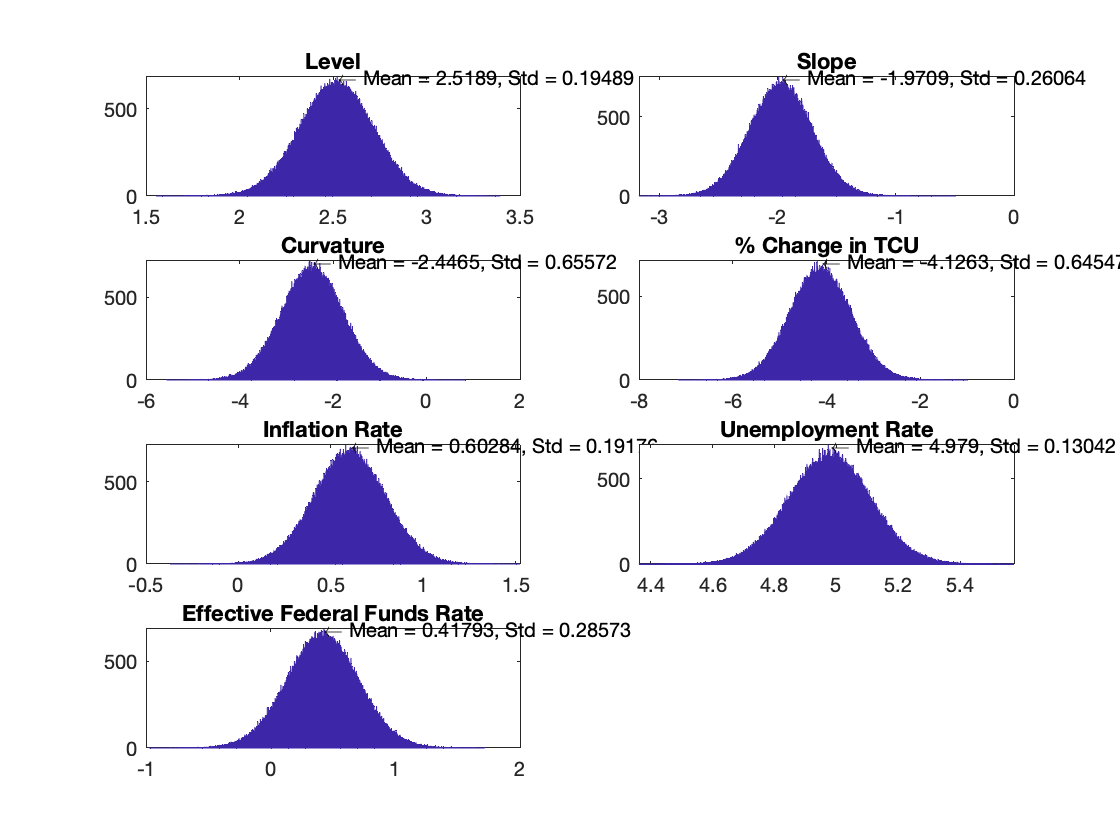


% average forecast and log predictive likelihood
if forecast == 1
    
    % mean forecast
    F_pred_mean = mean(F_pred,1); 
    
    % standard deviation of the forecast
    F_pred_std = std(F_pred,1);   
    log_pred_likhood = mean((log(pred_likhood)),1);

    % actual values of F at time T+h:
 
        true_value = F1(T+1,:);
    
 
    % ======= Plot the distribution of posterior predictive latent factors =====
    
    figure
    bars = 3000;
    
    
    var_names = {'Level','Slope','Curvature','% Change in TCU' , ...
    'Inflation Rate','Unemployment Rate', 'Effective Federal Funds Rate'};
    
    hold on;
    for i=1:size(betas_exog,2)
        subplot(4,2,i)
        hist(F_pred(:,i),bars);
        title(var_names{i})
        text(F_pred_mean(:,i),max(hist(F_pred(:,i),bars)),['\leftarrow Mean = '...
        num2str(F_pred_mean(:,i)) ', Std = ' num2str(F_pred_std(:,i))],...
        'HorizontalAlignment','left')
    
  
    end
    hold off;
    
end       

Current plot held


Current plot held


Current plot held


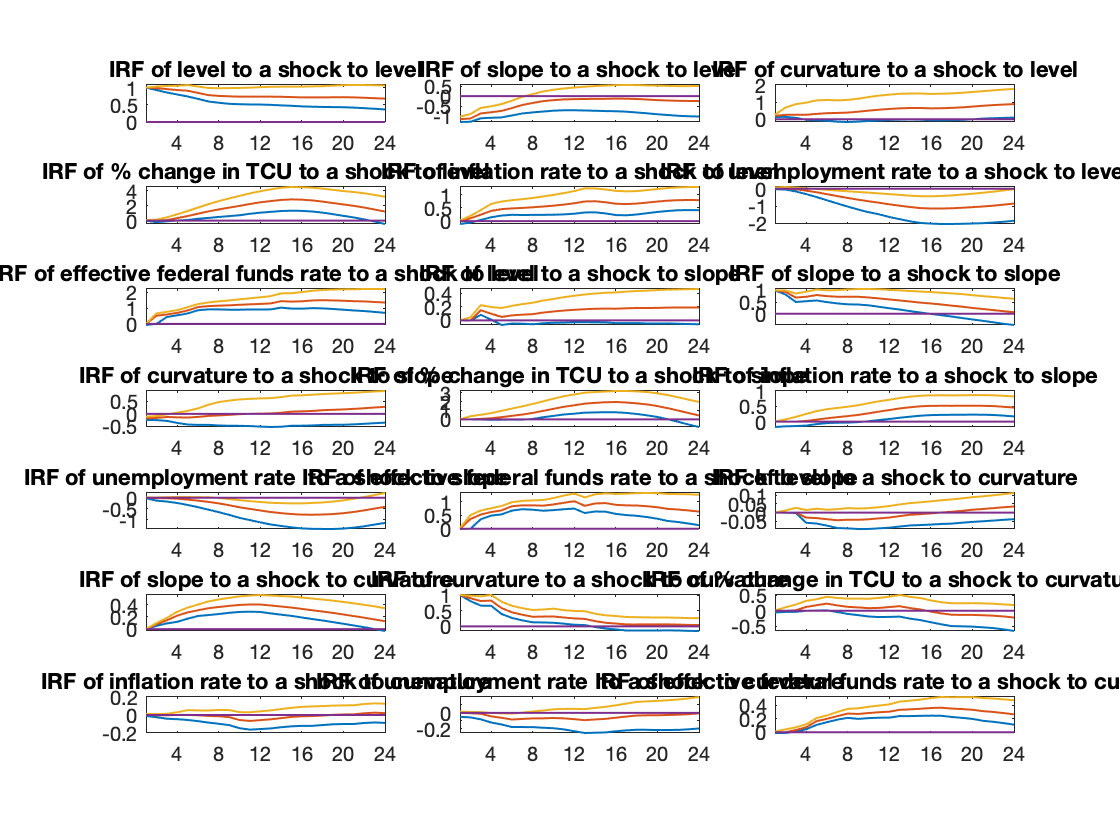

a = {24; 4; 8; 12; 16; 20};

% Obtain the graphs of impulse response functions
if impulses==1;
    
    % Affix quantiles from the posterior density of the impulse responses
    % posterior median : 50 th percentile
    % outer bands are 5 and 95 percentiles, respectively
    qus = [.05, .5, .95];
    

    imp_resp_level = squeeze(quantile(imp_level,qus));       
    imp_resp_slope = squeeze(quantile(imp_slope,qus));
    imp_resp_curv = squeeze(quantile(imp_curv,qus));
     
    imp_resp_tcu_ch = squeeze(quantile(imp_tcu_ch,qus));       
    imp_resp_pce_ch = squeeze(quantile(imp_pce_ch,qus));
    imp_resp_unrate = squeeze(quantile(imp_unrate,qus));
    imp_resp_effr = squeeze(quantile(imp_effr,qus));
    
    
    
    % ============== Plot the impulse response functions =====================
    
    
    figure
    set(0,'DefaultAxesColorOrder','factory',...
        'DefaultAxesLineStyleOrder','-|--|-')
    
   
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%% Shocks imposed on the level factor  %%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    subplot(7,3,1)
    plot(squeeze(imp_resp_level(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of level to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,2)
    plot(squeeze(imp_resp_slope(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10) 
    title('IRF of slope to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    
    subplot(7,3,3)
    plot(squeeze(imp_resp_curv(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of curvature to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,4)
    plot(squeeze(imp_resp_tcu_ch(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of % change in TCU to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,5)
    plot(squeeze(imp_resp_pce_ch(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10) 
    title('IRF of inflation rate to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,6)
    plot(squeeze(imp_resp_unrate(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of unemployment rate to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,7)
    plot(squeeze(imp_resp_effr(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of effective federal funds rate to a shock to level')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%% Shocks imposed on the slope factor  %%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    subplot(7,3,8)
    plot(squeeze(imp_resp_level(:,2,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of level to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,9)
    plot(squeeze(imp_resp_slope(:,2,:))','LineWidth',1)
    hold;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of slope to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,10)
    plot(squeeze(imp_resp_curv(:,2,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of curvature to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,11)
    plot(squeeze(imp_resp_tcu_ch(:,2,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of % change in TCU to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,12)
    plot(squeeze(imp_resp_pce_ch(:,2,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10) 
    title('IRF of inflation rate to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,13)
    plot(squeeze(imp_resp_unrate(:,2,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of unemployment rate  to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,14)
    plot(squeeze(imp_resp_effr(:,2,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of effective federal funds rate to a shock to slope')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%% Shocks imposed on the curvature factor  %%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    subplot(7,3,15)
    plot(squeeze(imp_resp_level(:,3,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of level to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,16)
    plot(squeeze(imp_resp_slope(:,3,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of slope to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,17)
    plot(squeeze(imp_resp_curv(:,3,:))','LineWidth',1)
    hold;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of curvature to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,18)
    plot(squeeze(imp_resp_tcu_ch(:,3,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of % change in TCU to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(7,3,19)
    plot(squeeze(imp_resp_pce_ch(:,3,:))','LineWidth',1)
    hold;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10) 
    title('IRF of inflation rate to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,20)
    plot(squeeze(imp_resp_unrate(:,3,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of unemployment rate  to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(7,3,21)
    plot(squeeze(imp_resp_effr(:,3,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',10)
    title('IRF of effective federal funds rate to a shock to curvature')
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)

end

Current plot held


Current plot held


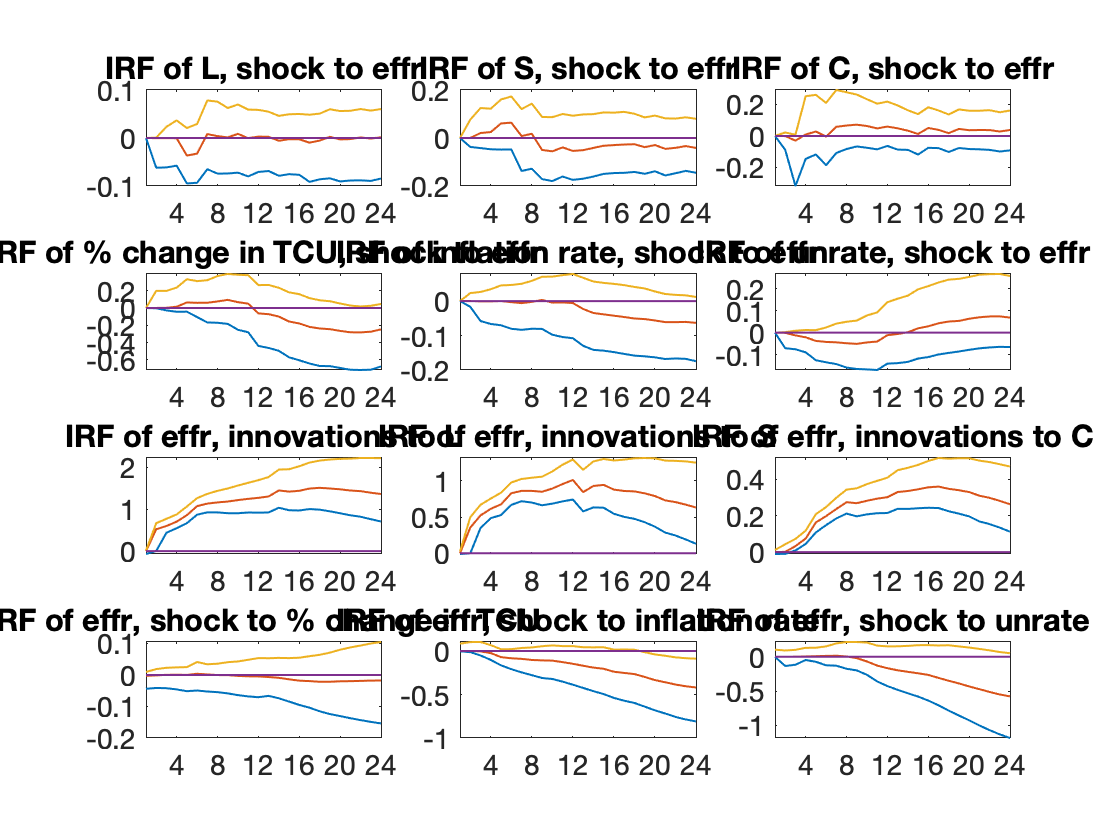

a = {24; 4; 8; 12; 16; 20};

% Obtain the graphs of impulse response functions
if impulses==1;
    
    % Affix quantiles from the posterior density of the impulse responses
    % posterior median : 50 th percentile
    % outer bands are 5 and 95 percentiles, respectively
    qus = [.05, .5, .95];
    

    imp_resp_level = squeeze(quantile(imp_level,qus));       
    imp_resp_slope = squeeze(quantile(imp_slope,qus));
    imp_resp_curv = squeeze(quantile(imp_curv,qus));
     
    imp_resp_tcu_ch = squeeze(quantile(imp_tcu_ch,qus));       
    imp_resp_pce_ch = squeeze(quantile(imp_pce_ch,qus));
    imp_resp_unrate = squeeze(quantile(imp_unrate,qus));
    imp_resp_effr = squeeze(quantile(imp_effr,qus));
    
    
    
    % ============== Plot the impulse response functions =====================
    
    
    figure
    set(0,'DefaultAxesColorOrder','factory',...
        'DefaultAxesLineStyleOrder','-|--|-')
    
   
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%% Shocks imposed on effr  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    subplot(4,3,1)
    plot(squeeze(imp_resp_level(:,7,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of L, shock to effr','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(4,3,2)
    plot(squeeze(imp_resp_slope(:,7,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14) 
    title('IRF of S, shock to effr','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    
    subplot(4,3,3)
    plot(squeeze(imp_resp_curv(:,7,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of C, shock to effr','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%% IRF of macro variables, shocks to effr  %%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    subplot(4,3,4)
    plot(squeeze(imp_resp_tcu_ch(:,7,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of % change in TCU, shock to effr','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(4,3,5)
    plot(squeeze(imp_resp_pce_ch(:,7,:))','LineWidth',1)
    hold;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of inflation rate, shock to effr','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(4,3,6)
    plot(squeeze(imp_resp_unrate(:,7,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of unrate, shock to effr','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%% IRF of effr, shocks to other variables  %%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    
    subplot(4,3,7)
    plot(squeeze(imp_resp_effr(:,1,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of effr, innovations to L','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(4,3,8)
    plot(squeeze(imp_resp_effr(:,2,:))','LineWidth',1)
    hold;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of effr, innovations to S','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(4,3,9)
    plot(squeeze(imp_resp_effr(:,3,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of effr, innovations to C','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(4,3,10)
    plot(squeeze(imp_resp_effr(:,4,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of effr, shock to % change in TCU','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    subplot(4,3,11)
    plot(squeeze(imp_resp_effr(:,5,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14) 
    title('IRF of effr, shock to inflation rate','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    
    
    
    subplot(4,3,12)
    plot(squeeze(imp_resp_effr(:,6,:))','LineWidth',1)
    hold on;
    plot(zeros(1,h_irf),'-', 'LineWidth',1)
    set(gca,'XTickLabel',a,'fontsize',14)
    title('IRF of effr, shock to unrate','FontSize', 18)
    xlim([1 h_irf])
    set(gca,'XTick',0:4:h_irf)
    

end

% Mean Squared Forecast error


MSFE = (F_pred_mean - true_value).^2; MSFE = MSFE';

colNames = {'MSFE'};
msfe_table = array2table(MSFE,'RowNames',var_names, ...
    'VariableNames',colNames);

disp_mfse = {"The mean squared forecast errors for the latent factors are:";...
    "----------------------------------";...
    msfe_table};

cellfun(@disp,disp_mfse)

The mean squared forecast errors for the latent factors are:
----------------------------------
                                     MSFE  
                                    _______

    Level                           0.28858
    Slope                           0.11679
    Curvature                        1.9941
    % Change in TCU                  1.6141
    Inflation Rate                  0.26357
    Unemployment Rate                2.9618
    Effective Federal Funds Rate    0.10754



% Print important results

disp_VARcoef_mean = {"The mean matrix of the VAR regression coefficients is:";...
    "----------------------------------";...
    round(VARcoef_mean, 4)};
cellfun(@disp,disp_VARcoef_mean)

The mean matrix of the VAR regression coefficients is:
----------------------------------
    0.0080    0.0213   -0.1631   -1.2112    0.1645    0.0226    0.0083
    0.9815    0.0268    0.1348   -0.0127    0.1110    0.0014    0.4663
    0.0041    0.9280    0.0009    0.0883    0.0158   -0.0108    0.3168
    0.0012    0.0787    0.9079    0.0205   -0.0019   -0.0010    0.0049
    0.0008    0.0002    0.0002    0.8841    0.0071   -0.0340    0.0024
   -0.0274    0.0012   -0.0456    0.0991    1.1991   -0.0045    0.0005
    0.0007    0.0019    0.0377   -0.2503   -0.0061    0.7951   -0.0146
   -0.0109   -0.0025   -0.0061    0.0282    0.0006   -0.0094    0.0067
   -0.0009    0.1811   -0.0244    0.1030    0.0224   -0.0144    0.1377
    0.1487    0.0009   -0.0072   -0.0299    0.0017    0.0157    0.2209
    0.0009    0.0009    0.0079    0.0055         0   -0.0009    0.0053
   -0.0011   -0.0001   -0.0018    0.0628    0.0276    0.0006    0.0014
   -0.0006    0.0054    0.0474    0.0241   -0.2921    0.02



disp_VARcoef_variance = {"The variance matrix of the VAR regression coefficients is:";...
    "----------------------------------";...
    round(VARcoef_std,4)};
cellfun(@disp,disp_VARcoef_variance)

The variance matrix of the VAR regression coefficients is:
----------------------------------
    0.0355    0.0559    0.2933    0.3731    0.1380    0.0520    0.0505
    0.0320    0.0590    0.1704    0.0965    0.0623    0.0157    0.1895
    0.0194    0.0437    0.0488    0.1290    0.0298    0.0245    0.1465
    0.0051    0.0118    0.0526    0.0402    0.0067    0.0037    0.0136
    0.0043    0.0019    0.0092    0.0603    0.0130    0.0082    0.0070
    0.0334    0.0252    0.1223    0.1119    0.0454    0.0190    0.0104
    0.0081    0.0147    0.1229    0.2798    0.0308    0.0672    0.0570
    0.0220    0.0180    0.0435    0.0709    0.0137    0.0176    0.0278
    0.0220    0.0966    0.1067    0.1669    0.0516    0.0290    0.2220
    0.0395    0.0245    0.0459    0.0970    0.0156    0.0307    0.1816
    0.0050    0.0065    0.0340    0.0323    0.0056    0.0040    0.0167
    0.0053    0.0015    0.0137    0.0738    0.0213    0.0047    0.0065
    0.0217    0.0297    0.1458    0.0826    0.0498    



disp_sigma_mean = {"The mean of the VAR covariance matrix is:";...
    "----------------------------------";...
    round(sigma_mean,4)};
cellfun(@disp,disp_sigma_mean)

The mean of the VAR covariance matrix is:
----------------------------------
    0.0355   -0.0362    0.0227    0.0007   -0.0006    0.0002   -0.0004
   -0.0362    0.0650   -0.0411   -0.0006   -0.0004   -0.0002    0.0005
    0.0227   -0.0411    0.3949   -0.0021    0.0004   -0.0002   -0.0001
    0.0007   -0.0006   -0.0021    0.3621         0   -0.0191   -0.0013
   -0.0006   -0.0004    0.0004         0    0.0323    0.0006    0.0005
    0.0002   -0.0002   -0.0002   -0.0191    0.0006    0.0152    0.0005
   -0.0004    0.0005   -0.0001   -0.0013    0.0005    0.0005    0.0764





disp_sigma_std = {"The variance of the VAR covariance matrix is:";...
    "----------------------------------";...
    round(sigma_std,4)};
cellfun(@disp,disp_sigma_std)

The variance of the VAR covariance matrix is:
----------------------------------
    0.0027    0.0032    0.0051    0.0030    0.0014    0.0007    0.0014
    0.0032    0.0048    0.0086    0.0036    0.0019    0.0008    0.0018
    0.0051    0.0086    0.0314    0.0103    0.0021    0.0020    0.0026
    0.0030    0.0036    0.0103    0.0294    0.0012    0.0046    0.0038
    0.0014    0.0019    0.0021    0.0012    0.0026    0.0011    0.0016
    0.0007    0.0008    0.0020    0.0046    0.0011    0.0012    0.0013
    0.0014    0.0018    0.0026    0.0038    0.0016    0.0013    0.0062




disp_pred_mean = {"The predictive mean is:";...
    "----------------------------------";...
    F_pred_mean, };
cellfun(@disp,disp_pred_mean)

The predictive mean is:
----------------------------------
    2.5189   -1.9709   -2.4465   -4.1263    0.6028    4.9790    0.4179




disp_pred_std = {"The predictive standard deviation is:";...
    "----------------------------------";...
    F_pred_std};
cellfun(@disp,disp_pred_std)

The predictive standard deviation is:
----------------------------------
    0.1949    0.2606    0.6557    0.6455    0.1918    0.1304    0.2857





disp_pred_likhood = {"The log predictive likelihood is:";...
    "----------------------------------";...
    log_pred_likhood};
cellfun(@disp,disp_pred_likhood)

The log predictive likelihood is:
----------------------------------
   -3.0456





disp_true_value = {"The true value of y(t+h) is:";...
    "----------------------------------";...
    true_value};
cellfun(@disp,disp_true_value)

The true value of y(t+h) is:
----------------------------------
    1.9817   -1.6292   -3.8587   -5.3968    1.1162    6.7000    0.0900




if prior_dist == 5 || prior_dist == 6
    

    if prior_dist == 5
        disp_ssvs_gamma = {"From SSVS prior, the average of the " + ...
            "gamma index restriction " ;...
        "----------------------------------";...
        gammas_mat};
        cellfun(@disp,disp_ssvs_gamma)

    elseif  prior_dist == 6  
        disp_ssvs_omega = {"From SSVS prior, the averages of the " + ...
        "omega index restriction index :";...
        "----------------------------------";...
        omega_mat};
        cellfun(@disp,disp_ssvs_omega)
        
    end
end

From SSVS prior, the averages of the omega index restriction index :
----------------------------------
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0








if prior_dist == 1; name = 'diffuse';
elseif prior_dist == 2; name = 'minnesota';
elseif prior_dist == 3; name = 'normal_wishart' ;
elseif prior_dist == 4; name = 'indep_normal_wishart';
elseif prior_dist == 5; name = 'SSVS_wishart';
elseif prior_dist == 6; name = 'SSVS_full';


end

## **References**

Diebold, F. X., & Li, C. (2006). Forecasting the term structure of government bond yields. *Journal of Econometrics,* *130*(2), 337-364. doi:10.1016/j.jeconom.2005.03.005

Diebold, F. X., Rudebusch, G. D., & Aruoba, S. B. (2006). The macroeconomy and the yield curve: A dynamic latent factor approach. *Journal of Econometrics,* *131*(1-2), 309-338. doi:10.1016/j.jeconom.2005.01.011

Diebold, Francis X., and Glenn D. Rudebusch. Yield Curve Modeling and Forecasting: The Dynamic Nelson-Siegel Approach. *Princeton University Press,* 2013. 

[https://www.mathworks.com/help/fininst/fitting-the-diebold-li-model_example-ex10300997.html](https://www.mathworks.com/help/fininst/fitting-the-diebold-li-model_example-ex10300997.html)

[https://www.mathworks.com/help/econ/using-the-kalman-filter-to-estimate-and-forecast-the-diebold-li-model.html](https://www.mathworks.com/help/econ/using-the-kalman-filter-to-estimate-and-forecast-the-diebold-li-model.html)